# INTERPOLACIÓ POLINOMIAL (primera part)

## APRENEM .....

### Polinomis i MATLAB®

Consulteu la pàgina [crear y evaluar polinomios](https://es.mathworks.com/help/matlab/math/create-and-evaluate-polynomials.html) y la pàgina [Raíces de polinomios](https://es.mathworks.com/help/matlab/ref/roots.html), ambdues de la documentació de MATLAB®. També us pot interesar la pàgina [Integrar y diferenciar polinomios](https://es.mathworks.com/help/matlab/math/integrate-and-differentiate-polynomials.html).

Després de llegir els dos primers documents, calculeu:

- les arrels del polinomi cúbic (grau 3)  $x^3+4x^2+4x=0$ 

- avalueu el polinomi  $x^5-1$ per $x=2$

- coficients del polinomi d'arrels els enters  -5,-2, -1, 1, 2, i 8. Quin grau té?

% p=[]                   % vector amb els coeficients del polinomi 
                         % arrels
% p=[ ]                  % vector amb els coeficients del polinomi 
                         % valor polinomi
% r=[ ]                  % vector amb les arrels
                         % coeficients polinomi d'arrels r

### Polinomi interpolador

Baixeu-vos del campus el codi de polyinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab". *Consulteu la pàgina 5 i reproduïu el seu exemple. 

x = 1:6; y = [16 18 21 17 15 12]; disp([x;y]);

     1     2     3     4     5     6
    16    18    21    17    15    12



u = 0.75:0.05:6.25;

polyinterp(x,y,5.4) % aplicamos el polinomio en un punto

ans = 15.1538

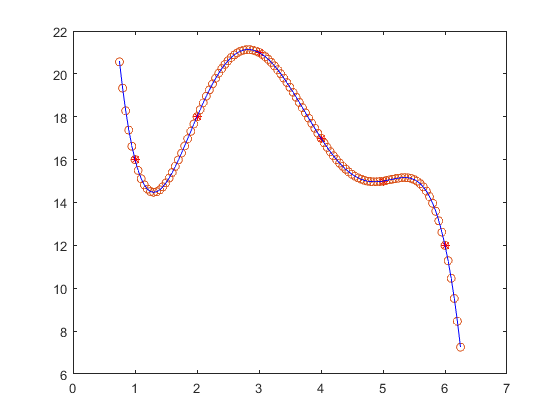

v = polyinterp(x,y,u); % aplicamos el polinomio a muchos puntos y simulamos la linea
plot(x,y,'red*',u,v,'o',u,v,'blue-');

La rutina polyinterp.m s'obtenen els valors del polinomi interpolador a la taula [x;y] i permet fer la seva representació gràfica. En cap cas obtenim els coeficients del polinomi interpolador. 

Els coeficients del polinomi interpolador es poden obtenir amb polifit, i els valors aproximats amb polyval. Consulteu [polyfit](https://es.mathworks.com/help/matlab/ref/polyfit.html)

grau = length(x) - 1;
p = polyfit(x,y,grau)   % Coeficientes del polinomio de grado 'grau'

p =    -0.2417    4.3333  -28.9583   87.6667 -115.8000   69.0000


polyval(p,x)

ans =    16.0000   18.0000   21.0000   17.0000   15.0000   12.0000


## PRACTIQUEM ....

### 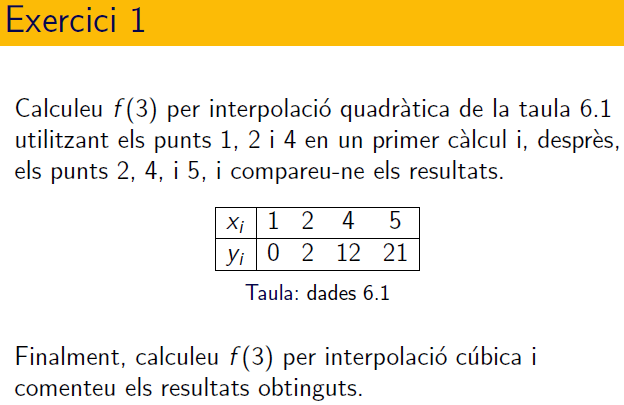

Aquest exercici s'ha de resoldre fent ús de **polyinterp**

% primer càlcul
% segon  càlcul
% tercer  càlcul

### 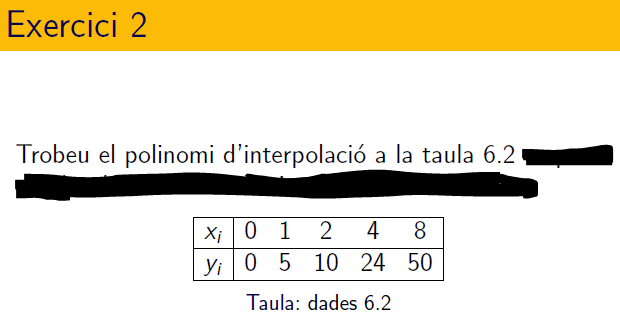

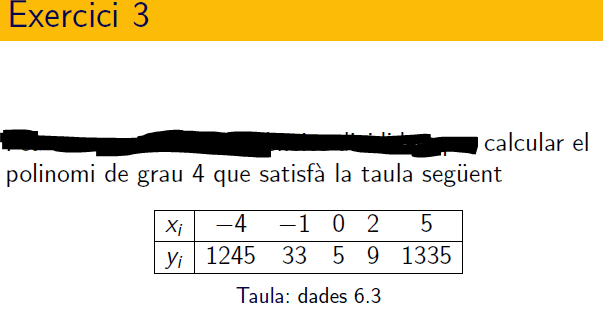

## 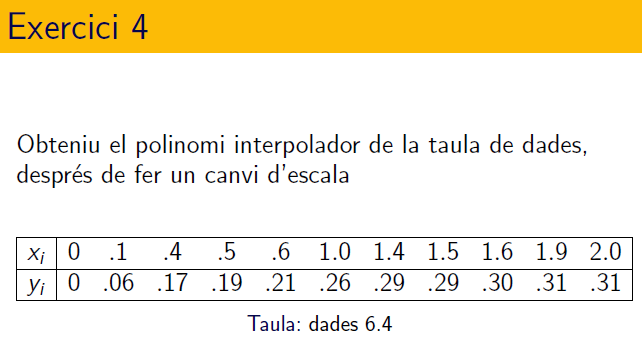

Baixeu-vos del campus el codi de rungeinterp.m. Aquest codi és el que C. Moler explica en el chapter 3 dels seus apunts *"Numerical Computing with Matlab". *Consulteu l'exercici 3.9 de la pàgina 23. 

a) Experimenteu la interpolació de la funció f(x) per n=2,3,7,11,13,17,19,23,29 ... o altres valors en punts equiespaiats fent ús de rungeinterp.m i polyinterp.m

% rungeinterp()

Responeu: Per a quins x de l'interval [-1,1] és compleix $P_n(x) \rightarrow f(x)$ per $n \rightarrow \infty$?

b) Experimenteu la interpolació de la funció f(x) per n=2,3,7,11,13,17,19,23,29 ... o altres valors fent en punts no EQUIESPAIATS fent ús de interp_gadget.m i polyinterp.m

% interp_gadget()

Responeu: Per a quin tipus d'abscises és compleix $P_n(x) \rightarrow f(x)$ per $n \rightarrow \infty$ per a tot x de l'interval [-1,1] ?